% CNMFE_Noise_Cleaner_v1
% 编写时间：2026/1/14
% 编写人：WXW
% 对 CNMFE 结果中的噪音进行去除

clear
close all
clc

load('NewMr_results.mat');
NeuronA = reshape(neuron.A,Ysiz(1),Ysiz(2),[]);
NeuronA_peak = squeeze(max(max(NeuronA, [], 1), [], 2));
NeuronA_size = squeeze(sum(NeuronA ~= 0, [1 2]));

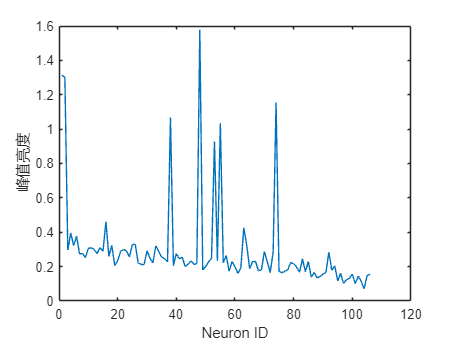

% 所有 neuron 的峰值亮度图
figure
plot(NeuronA_peak)
xlabel('Neuron ID')
ylabel('峰值亮度')

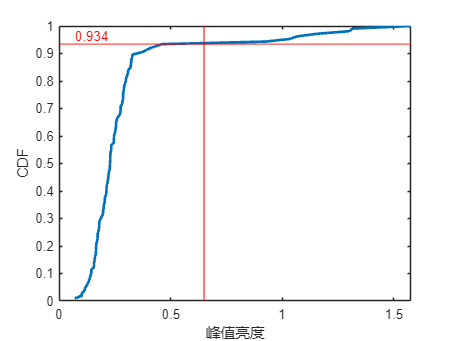


neuronID = reshape(1:size(NeuronA,3), [], 1);
NeuronA_peak2 = horzcat(neuronID, NeuronA_peak);
NeuronA_peak2_sorted = sortrows(NeuronA_peak2, 2, 'ascend');

% 所有 neuron 的峰值亮度CDF图
figure
x1 = NeuronA_peak2_sorted(:,2);
N1 = length(x1);
y1 = (1:N1) / N1;
plot(x1, y1, 'LineWidth', 2)
xlabel('峰值亮度')
ylabel('CDF')
hold on

idx95 = min(ceil(0.95 * N1), N1);
x95_peak = x1(idx95);

maxValue_peak = ceil(max(NeuronA_peak) * 100) / 100;
threshold_peak = 0.65;
xline(threshold_peak, 'r', 'LineWidth', 1);
y_thr_peak = sum(x1 <= threshold_peak) / N1;
yline(y_thr_peak, 'r', 'LineWidth', 1);

text(min(x1), y_thr_peak, ...
    sprintf('%.3f', y_thr_peak), ...
    'Color','r', 'VerticalAlignment','bottom');
hold off


noise = NeuronA_peak2_sorted(NeuronA_peak2_sorted(:,2) > threshold_peak, 1);

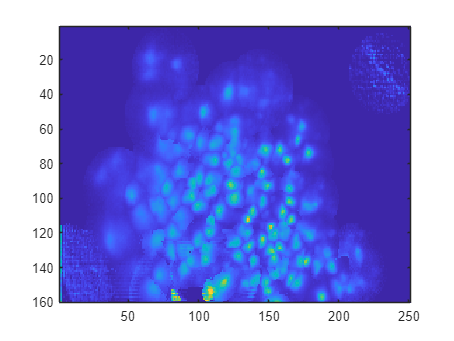

neuron_ture = setdiff(neuronID, noise);
NeuronA1 = NeuronA(:,:,neuron_ture);
SFP1 = max(NeuronA1,[],3);
figure
imagesc(SFP1);

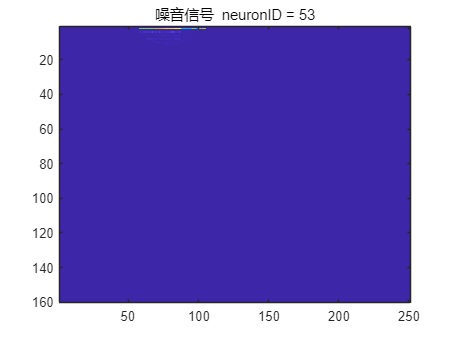

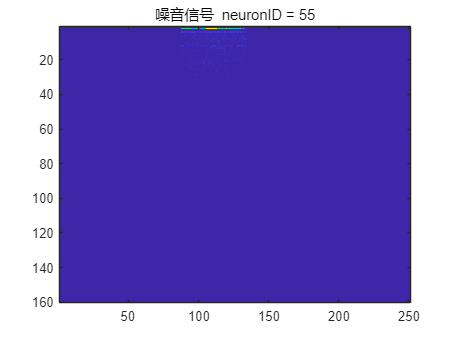

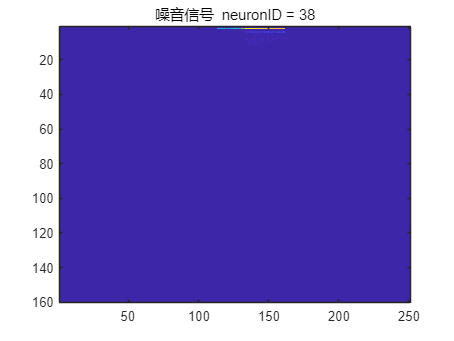

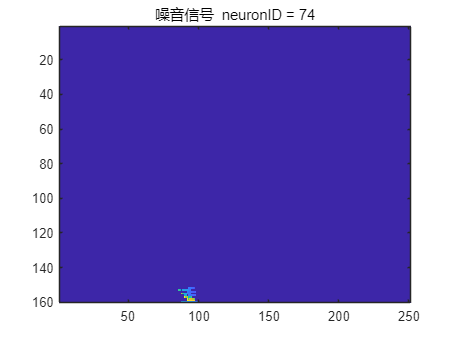

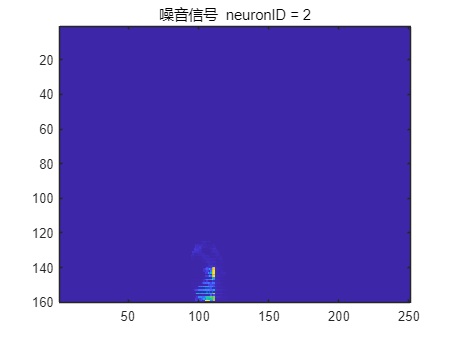

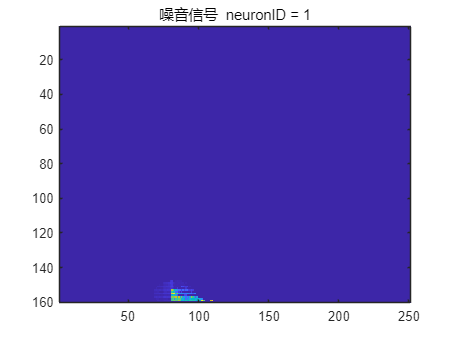

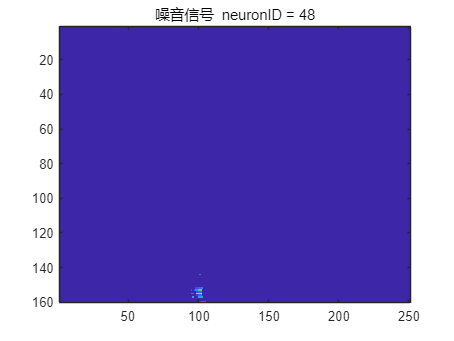


noise_figure = NeuronA(:,:,noise);
if ~isempty(noise_figure)

    for fi = 1:length(noise)
        figure
        imagesc(NeuronA(:,:,noise(fi)));
        title(['噪音信号  neuronID = ' num2str(noise(fi))])
    end
end